# **Tutorial I: Gaussian Process Regression**

### Acknowledgment

- This tutorial was prepared by Najee Stubbs at the University of Arkansas (nistubbs@uark.edu) and revised following comments from Ryan Weinstein (rweinste@mathworks.com).

- The development of this tutorial was supported by a gift from MathWorks through the MathWorks Curriculum Development Support program. (Mehdi Vabab, mvahab@mathworks.com)

- The algoirthms used in this tutorial are adopted from *J. K. Hoskins, H. Hu, and M. Zou, “Exploring Machine Learning and Machine Vision in Femtosecond Laser Machining,” ASME Open Journal of Engineering, 2023, 2: 024501. [*[*link*](https://asmedigitalcollection.asme.org/openengineering/article/doi/10.1115/1.4063646/1169944)*]*. The data used in this tutorial is from *C. Dunlap, H. Pandey, E. Weems, and H. Hu, “Nonintrusive Heat Flux Quantification Using Acoustic Emissions During Pool Boiling,” Appl. Therm. Eng., 228, (2023) 120558. [*[*link*](http://%284%29c.%20dunlap%2C%20h.%20pandey%2C%20e.%20weems%2C%20and%20h.xn--%20hu%2C%20nonintrusive%20heat%20flux%20quantification%20using%20acoustic%20emissions%20during%20pool%20boiling%2C%20appl-z591fqg.%20therm.%20eng.%2C%20228%2C%20%282023%29%20120558.)*]*

- This tutorial was implemented in MEEG tech elective "Machine Learning for Mechanical Engineers." [[link](https://github.com/hanhuark/MEEG-54403/tree/main)]

### Machine Learning for Mechanical Engineers - Tutorials Overview

These tutorials aim to equip learners with the necessary skills to apply machine learning techniques and expedite the development of engineering solutions for their specialized problems. The interactive tutorials offer live controls that enable users to manipulate key parameters and observe the real-time impact on the code's performance and accuracy. They also include concept checks and external links for further comprehension of specific concepts. Additionally, some of the tutorials in this series present alternative workflows and recommendations for parallelization. These tutorials are designed to assist engineering educators in integrating user-friendly, self-contained introductory modules into their lesson plans, requiring nothing more than the module itself and its associated dataset.

### Introduction

This tutorial focuses on two regression methods, i.e., Gaussian Process Regression (GRP) and Multilayer Perceptron (MLP) neural networks with a linear regressor. GPR is a non-parametric Bayesian-based regression approach. scikit learn has a very nice article on Gaussian Process [[link](https://scikit-learn.org/stable/modules/gaussian_process.html)]. Wang at the University of Waterloo also wrote a feature article on GPR [[link](https://arxiv.org/pdf/2009.10862.pdf)]. MLP is a type of neural networks suitable for a variety of applications (e.g, classification, regression). In this tutorial, we will focus on an MLP model using ReLU activation function in the hidden layers and linear activation function for regression. 

This tutorial uses temperature-based heat flux predictions in pool boiling as the test case. In pool boiling experiments, the boiling heat flux can be estimated as the supplied power divided by the heater surface. However, this estimation will not be very accurate due to heat loss and other non-ideal conditions in experiments, especially for thin-film heaters with relatively low thermal conductivities (e.g., ITO heaters). Conventionally, finite-element simulations are used to evaluate the heat loss to validate or correct the experimental assumptions. Machine learning provides another perspective for tackling this issue. The heat loss and other non-ideal conditions can be captured and accounted for by the hidden layers of neural networks. The target of this problem is to develop a GPR model and an MLP model to predict heat flux using temperature and compare their performance. The data set includes the temperature and the heat flux during a transient pool boiling test. Specifically, 

- Set up and train an MLP and a GPR model to predict the heat flux based on the temperature. Report the training curves (training/validation accuracy/loss vs. epoch) and the training time (time/epoch, time till the best model).

- Circumvent the effects of overfitting using k-fold cross-validation (e.g., using 100 foldings). 

Sec. 1: Load data from the selected file and plot the raw data. This tutorial uses the temperature and heat flux data provided for Assignment 1 of the machine learning class.  

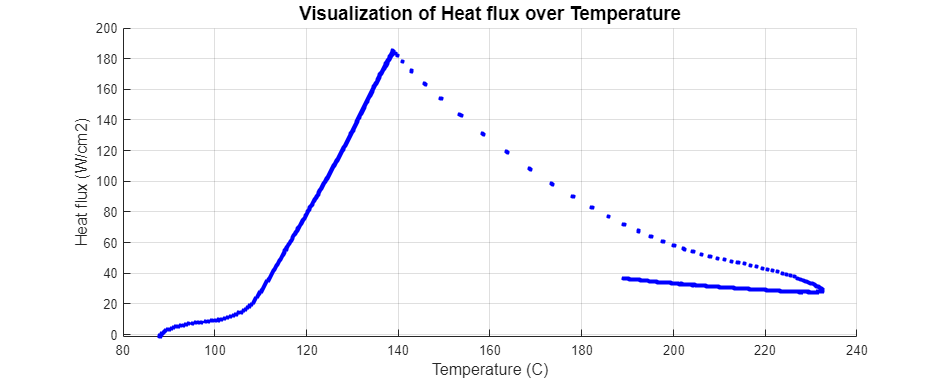

[temperature, heatflux] = loadData();

Sec. 2: Split dataset into training and validation

originalDataset = partitionData(temperature, heatflux);

X_train_val = [originalDataset.X_train; originalDataset.X_val];
y_train_val = [originalDataset.y_train; originalDataset.y_val];

Sec. 3: Set up k-fold cross-validation, train and test MLP models.

K = 2;

[best_mlp_model, best_mlp_rmse] = performKFoldsCrossValidation(X_train_val, y_train_val, K, 'MLP');

Processing fold 1/2...
Training on single GPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     RMSE     |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       115.16 |       108.68 |    6630.8262 |    5906.2095 |          0.0100 |
|       1 |          50 |       00:00:00 |        70.39 |        71.20 |    2477.6345 |    2534.9229 |          0.0100 |
|       2 |         100 |       00:00:01 |        16.73 |        17.77 |     140.0219 |     157.9167 |          0.0100 |
|       3 |         150 |       00:00:01 |         7.68 |         5

Test RMSE for MLP: 4.2489


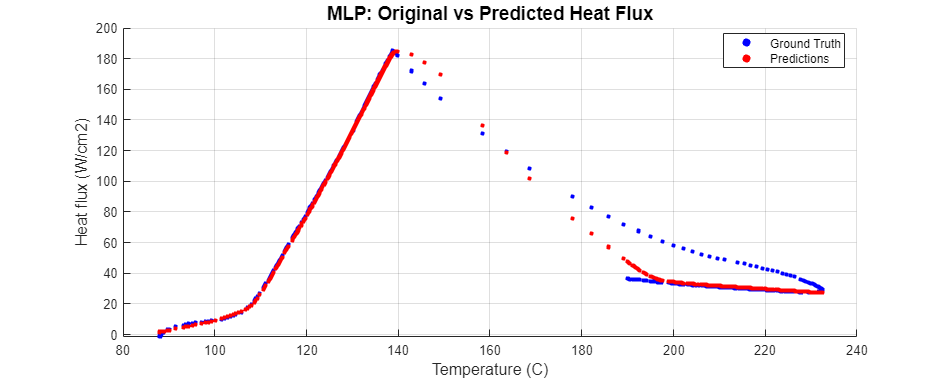

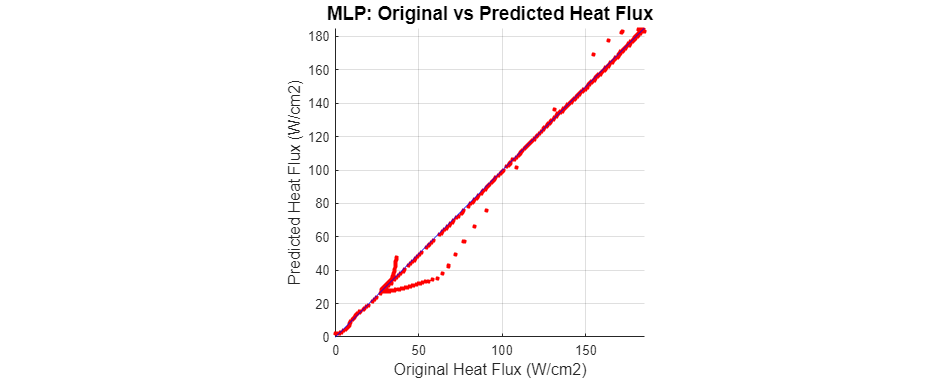

residuals_MLP = evaluateModel(best_mlp_model, originalDataset, 'MLP');

Sec. 4: Set up k-fold cross-validation, train and test GPR models.

[best_gpr_model, best_gpr_rmse] = performKFoldsCrossValidation(X_train_val, y_train_val, K, 'GPR');

Processing fold 1/2...
Processing fold 2/2...
Best RMSE for GPR: 3.4127 (from fold 2)


Test RMSE for GPR: 3.7556


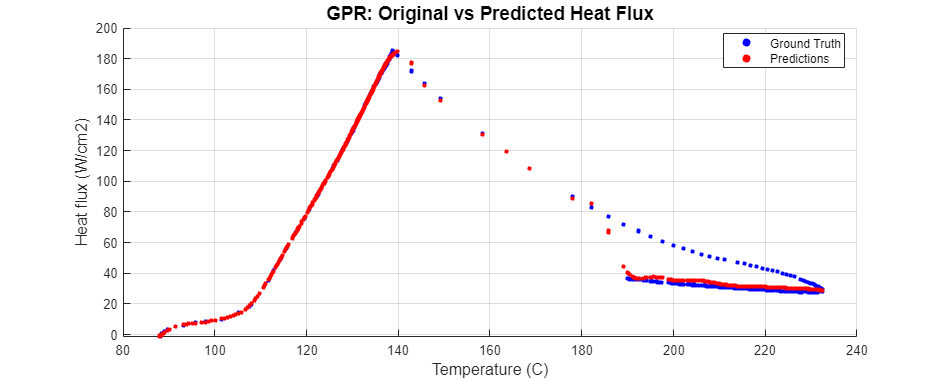

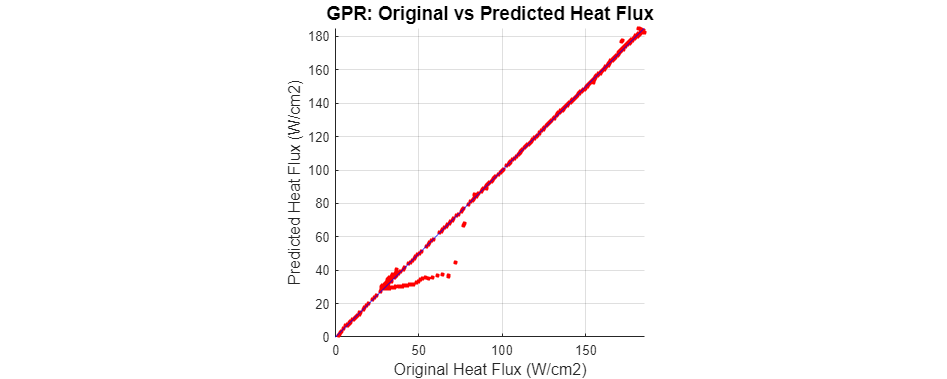

residuals_GPR = evaluateModel(best_gpr_model, originalDataset, 'GPR');

Sec. 5: Compare MLP and GRP predictions

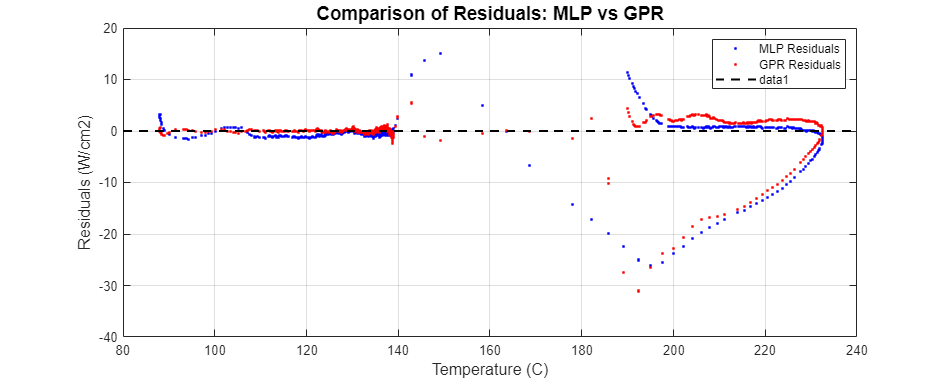

compareResiduals(originalDataset.X_test, residuals_MLP, residuals_GPR);

## Data Loading Function

function [temperature, heatflux] = loadData()
    [filename, filepath] = uigetfile('*.txt', 'Select a data file');
    data = readtable(fullfile(filepath, filename), ...
        'Delimiter', '\t', ...
        'VariableNamingRule', 'preserve', ...
        'HeaderLines', 1);
    temperature = data{:,1};
    heatflux = data{:,2};
    visualizeData(temperature, heatflux, 'Visualization of Heat flux over Temperature');
end

## Visualization Function

function visualizeData(x, y, titleText, pred)
    figure('Position', [10, 10, 1000, 400]);
    scatter(x, y, 10, 'b', 'filled');
    hold on;
    if nargin == 4
        scatter(x, pred, 10, 'r', 'filled');
        legend('Ground Truth', 'Predictions', 'Location', 'best');
    end
    xlabel('Temperature (C)', 'FontSize', 12);
    ylabel('Heat flux (W/cm2)', 'FontSize', 12);
    title(titleText, 'FontSize', 14);
    grid on;
    hold off;
end

## Data Splitting Functions

function data_partitions = partitionData(temperature, heatflux)
    
    test_ratio = 0.2;
    val_ratio = 0.1;

    c1 = cvpartition(length(heatflux), 'Holdout', test_ratio);

    X_temp = temperature(c1.training);
    y_temp = heatflux(c1.training);

    X_test = temperature(c1.test);
    y_test = heatflux(c1.test);

    c2 = cvpartition(length(y_temp), 'Holdout', val_ratio);

    X_train = X_temp(c2.training);
    y_train = y_temp(c2.training);

    X_val = X_temp(c2.test);
    y_val = y_temp(c2.test);

    data_partitions = struct('X_train', X_train, 'y_train', y_train, ...
                             'X_val', X_val, 'y_val', y_val, ...
                             'X_test', X_test, 'y_test', y_test);
end

function [train_val_partitions] = kFoldPartitionData(X_train_val, y_train_val, K)

    c = cvpartition(length(y_train_val), 'KFold', K);
    
    train_val_partitions = cell(K, 1);
    
    for i = 1:K

        X_train = X_train_val(c.training(i));
        y_train = y_train_val(c.training(i));
        X_val = X_train_val(c.test(i));
        y_val = y_train_val(c.test(i));
        
        dataset_fold = struct('X_train', X_train, 'y_train', y_train, ...
                              'X_val', X_val, 'y_val', y_val);
        train_val_partitions{i} = dataset_fold;
    end
end

## KFolds function

function [best_model, best_rmse] = performKFoldsCrossValidation(X_train_val, y_train_val, K, modelType)

    train_val_partitions = kFoldPartitionData(X_train_val, y_train_val, K);
    
    rmse_values = zeros(K, 1);
    models = cell(K, 1);
    
    for i = 1:K
        fprintf('Processing fold %d/%d...\n', i, K);
        
        dataset_fold = train_val_partitions{i};
        
        switch modelType
            case 'MLP'
                model = trainMLPModel(dataset_fold);
            case 'GPR'
                model = trainGPRModel(dataset_fold);
        end
        
        y_val_pred = predict(model, dataset_fold.X_val);
        residuals = y_val_pred - dataset_fold.y_val;
        
        rmse_values(i) = sqrt(mean(residuals.^2));
        models{i} = model;
    end
    
    [~, best_idx] = min(rmse_values);
    best_model = models{best_idx};
    best_rmse = rmse_values(best_idx);
    
    fprintf('Best RMSE for %s: %.4f (from fold %d)\n', modelType, best_rmse, best_idx);
end

## MLP Model Building and Training Function

function [net] = trainMLPModel(dataset)
    layers = [
        featureInputLayer(1, 'Normalization', 'zscore', 'Name', 'input')
        fullyConnectedLayer(128, 'WeightsInitializer', 'he', 'Name', 'fc1', 'WeightL2Factor', 0.001)
        leakyReluLayer(0.01, 'Name', 'lrelu1')
        fullyConnectedLayer(64, 'WeightsInitializer', 'he', 'Name', 'fc2', 'WeightL2Factor', 0.001)
        leakyReluLayer(0.01, 'Name', 'lrelu2')
        fullyConnectedLayer(32, 'WeightsInitializer', 'he', 'Name', 'fc3', 'WeightL2Factor', 0.001)
        leakyReluLayer(0.01, 'Name', 'lrelu3')
        fullyConnectedLayer(1, 'WeightsInitializer', 'he', 'Name', 'fc4')
        regressionLayer('Name', 'output')];

    options = trainingOptions('adam', ...
        'InitialLearnRate', 0.01, ...
        'LearnRateSchedule', 'piecewise', ...
        'LearnRateDropFactor', 0.15, ...
        'LearnRateDropPeriod', 15, ...
        'MaxEpochs', 5, ...
        'MiniBatchSize', 32, ...
        'Verbose', true, ...
        'ValidationData', {dataset.X_val, dataset.y_val}, ...
        'ValidationPatience', 5,...
        'OutputNetwork','best-validation-loss',...
        'Shuffle', 'every-epoch', ...
        'ExecutionEnvironment', 'auto');

    [net] = trainNetwork(dataset.X_train, dataset.y_train, layers, options);
end

## GPR Model Building and Training Function

function gprMdl = trainGPRModel(dataset)
    gprMdl = fitrgp(dataset.X_train, dataset.y_train, ...
        'KernelFunction', 'squaredexponential', ...
        'Standardize', true, ...
        'Verbose', 0);
end

## Model Evaluation Function

function residuals = evaluateModel(model, dataset, modelType)
    y_test_pred = predict(model, dataset.X_test);
    
    residuals = y_test_pred - dataset.y_test;
    
    mse_test = mean(residuals.^2);
    rmse_test = sqrt(mse_test);
    fprintf('Test RMSE for %s: %.4f\n', modelType, rmse_test);

    visualizeData(dataset.X_test, dataset.y_test, sprintf('%s: Original vs Predicted Heat Flux', modelType), y_test_pred);

    figure('Position', [10, 10, 1000, 400]);
    scatter(dataset.y_test, y_test_pred, 10, 'ro', 'filled');
    xlabel('Original Heat Flux (W/cm2)', 'FontSize', 12);
    ylabel('Predicted Heat Flux (W/cm2)', 'FontSize', 12);
    title(sprintf('%s: Original vs Predicted Heat Flux', modelType), 'FontSize', 14);
    axis equal;
    grid on;
    hold on;
    max_val = max([dataset.y_test; y_test_pred]);
    min_val = max(0, min([dataset.y_test; y_test_pred]));
    axis([min_val max_val min_val max_val]);
    plot([min_val, max_val], [min_val, max_val], 'b-');
    hold off;
end

## Residuals Comparison Function

function compareResiduals(X_test, residuals_MLP, residuals_GPR)
    figure('Position', [10, 10, 1000, 400]);
    plot(X_test, residuals_MLP, 'b.', 'DisplayName', 'MLP Residuals');
    hold on;
    plot(X_test, residuals_GPR, 'r.', 'DisplayName', 'GPR Residuals');
    
    line(xlim, [0 0], 'Color', 'k', 'LineStyle', '--', 'LineWidth', 1.5); 
    
    xlabel('Temperature (C)', 'FontSize', 12);
    ylabel('Residuals (W/cm2)', 'FontSize', 12);
    title('Comparison of Residuals: MLP vs GPR', 'FontSize', 14);
    legend('show');
    grid on;
    hold off;
end

# **END OF TUTORIAL**

# Topic I: Regression

**Revised on May 21, 2024 @ 9:400 pm**

**Created by Najee I. Stubbs; {nistubbs@uark.edu}**

**University of Arkansas, College of Engineering, Mechanical Engineering Department**